# 最急降下法

clear;clc;close all;

シンボリック変数を定義し，関数fとその微分dfを計算する

syms x f df
f=(x-1)*x*(x+1)

$$f = x\,\left(x-1\right)\,\left(x+1\right)$$

df=simplify(diff(f,x))

$$df = 3\,x^{2}-1$$

(この問題では極値となるxを求められる)

solve(df==0)

$$ans = \left[\begin{array}{c} -\frac{\sqrt{3}}{3}\\ \frac{\sqrt{3}}{3} \end{array}\right]$$

最急降下法

xVal=1;rho=0.15;
for n1=1:10
    xOld=xVal(end);
    xNew=xOld-rho*subs(df,x,xOld);
    xVal=[xVal;xNew];
end

double(xVal)

ans =     1.0000
    0.7000
    0.6295
    0.6012
    0.5885
    0.5827
    0.5799
    0.5786
    0.5779
    0.5776



figure
fplot(f);grid on;hold on;
set(gca,'fontname','メイリオ','FontSize',12);
xlim([-1 1]*1.2);
plot(xVal,subs(f,xVal),'ro');
xlabel('$x$','Interpreter','latex');
ylabel('$f(x)$','Interpreter','latex');


初期値を変えてみる

xVal=-0.3;rho=0.15;
for n1=1:10
    xOld=xVal(end);
    xNew=xOld-rho*subs(df,x,xOld);
    xVal=[xVal;xNew];
end

double(xVal)

ans =    -0.3000
   -0.1905
   -0.0568
    0.0917
    0.2379
    0.3625
    0.4533
    0.5109
    0.5434
    0.5605


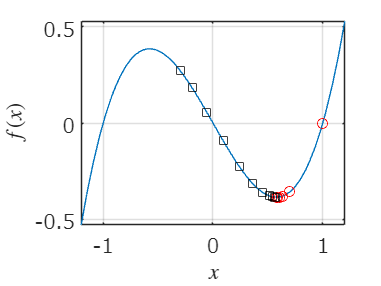


plot(xVal,subs(f,xVal),'ks');
exportgraphics(gcf,'fig_steepestDescent.pdf');